## Practica desde semana 1 hasta semana 3

### Semana 1 martes

### Ejercicio 1

format long
e= expo(0.5,3)

e =    1.645833333333333


### Ejercicio 2

A=6.737947*10^(-3)

A =    0.006737947000000


n=20;x=5;
%metodos
m1= expo(-x,n)

m1 =    0.006745540097712


m2= 1/expo(x,n)

m2 =    0.006737947545483



%error absoluto
E_a1 =abs(A-m1)

E_a1 =      7.593097711817119e-06


E_a2 =abs(A-m2)

E_a2 =      5.454825098560878e-10



%error relativo
E_r1=E_a1/A

E_r1 =    0.001126915618632


E_r2=E_a2/A

E_r2 =      8.095678251195621e-08



%cifras significativas
cs1= cifras_sig(E_r1)

cs1 =      3


cs2= cifras_sig(E_r2)

cs2 =      7


### Ejercicio 3

x=3*pi;
result=coseno(x)

result =   -0.999999980962160


### Ejercicio 4

A=[0.2 0.5 -0.1; -0.1 0.2 -0.3; 0.2 0 0.5];
resut= expo_matrix(A)

resut =    1.171045932192708   0.602632163541667  -0.241568898869048
  -0.160873921428571   1.184495095099455  -0.415375949751984
   0.281400354136905   0.067245814533730   1.626769370664931


## Semana 1 Jueves

### Ejercicio 1

syms R1 R2

%Para "Serie"
%error relativos
er1=4;er2=2;

f1=R1+R2

$$f1 = R_{1}+R_{2}$$

%diferencial de f1
df1_1=diff(f1,{R1})

$$df1\_1 = 1$$

df1_2=diff(f1,{R2})

$$df1\_2 = 1$$


%error relativo final
erf_serie= abs(df1_1)*er1 +abs(df1_2)*er2

$$erf\_serie = 6$$


%para "paralelo"
f2= R1*R2/(R1+R2)

$$f2 = \frac{R_{1}\,R_{2}}{R_{1}+R_{2}}$$

df2_1=diff(f2,{R1})

$$df2\_1 = \frac{R_{2}}{R_{1}+R_{2}}-\frac{R_{1}\,R_{2}}{{\left(R_{1}+R_{2}\right)}^{2}}$$

df2_2=diff(f2,{R2})

$$df2\_2 = \frac{R_{1}}{R_{1}+R_{2}}-\frac{R_{1}\,R_{2}}{{\left(R_{1}+R_{2}\right)}^{2}}$$

erf2=simplifyFraction(abs(df2_1)*er1 + abs(df2_2)*er2)

$$erf2 = \frac{2\,{\left|R_{1}\right|}^{2}}{{\left|R_{1}+R_{2}\right|}^{2}}+\frac{4\,{\left|R_{2}\right|}^{2}}{{\left|R_{1}+R_{2}\right|}^{2}}$$

erf2_paralelo= double(subs(erf2,{R1,R2},{20,300}))

erf2_paralelo =    3.523437500000000


### Ejericio 2

syms Rl Vs Rs
erRl=0.01;erVs=0.12;erRs=0.015%2.51-2.48/2

erRs =    0.015000000000000



P= (Vs^2*Rl)/(Rl+Rs)^2

$$P = \frac{\mathrm{Rl}\,{\mathrm{Vs}}^{2}}{{\left(\mathrm{Rl}+\mathrm{Rs}\right)}^{2}}$$

df_rl=diff(P,{Rl})

$$df\_rl = \frac{{\mathrm{Vs}}^{2}}{{\left(\mathrm{Rl}+\mathrm{Rs}\right)}^{2}}-\frac{2\,\mathrm{Rl}\,{\mathrm{Vs}}^{2}}{{\left(\mathrm{Rl}+\mathrm{Rs}\right)}^{3}}$$

df_vs=diff(P,{Vs})

$$df\_vs = \frac{2\,\mathrm{Rl}\,\mathrm{Vs}}{{\left(\mathrm{Rl}+\mathrm{Rs}\right)}^{2}}$$

df_rs=diff(P,{Rs})

$$df\_rs = -\frac{2\,\mathrm{Rl}\,{\mathrm{Vs}}^{2}}{{\left(\mathrm{Rl}+\mathrm{Rs}\right)}^{3}}$$


erf_P=simplifyFraction(abs(df_rl)*erRl + abs(df_vs)*erVs + abs(df_rs)*erRs)

$$erf\_P = \frac{3\,\left|\mathrm{Rl}\right|\,{\left|\mathrm{Vs}\right|}^{2}+24\,\left|\mathrm{Rl}+\mathrm{Rs}\right|\,\left|\mathrm{Rl}\,\mathrm{Vs}\right|+{\left|\mathrm{Vs}\right|}^{2}\,\left|\mathrm{Rl}-\mathrm{Rs}\right|}{100\,{\left|\mathrm{Rl}+\mathrm{Rs}\right|}^{3}}$$

Erf=double(subs(erf_P,{Rl,Vs,Rs},{10,12,2.495}))

Erf =    0.212152439507816


### Ejercicio 3

%converir 168 a base 2
dec2bin(168)

ans = '10101000'

%Convertir el binario ’1011011’ a decimal
bin2dec('1011011')

ans =     91


%Convertir 732 a base 4
dec2base(732,4)

ans = '23130'

%Convertir ’1452332’ en base 6 a decimal
base2dec('1452332',6)

ans =        84800


%Convertir '122110' en base 3 a base 5.
dec2base(base2dec('122110',3),5)

ans = '3341'

%Convertir 543 a hexadecimal
dec2hex(543)

ans = '21F'

%Convertir ’1FA’ a decimal
hex2dec('1FA')

ans =    506


### Ejercicio 4

%Convertir 0.101001, base 2, a base decimal
b='101001';
N=bin2dec(b)*2^(-length(b))

N =    0.640625000000000



%Convertir 111100.110001 (base 2) a base decimal
entero='111100'

entero = '111100'

decimal='110001'

decimal = '110001'

dec_entera=bin2dec(entero)

dec_entera =     60


dec_frac=bin2dec(decimal)*2^(-length(decimal));
N=dec_frac+dec_entera

N =   60.765625000000000



%presicion simple
N1=sprintf('%tx',625)

N1 = '441c4000'

N2=hex2dec(N1)

N2 =      1.142702080000000e+09


N=dec2bin(N2)

N = '1000100000111000100000000000000'

length(N)

ans =     31


N=strcat('0',N)

N = '01000100000111000100000000000000'


%presicion doble
N1=sprintf('%bx',625)

N1 = '4083880000000000'

N2=hex2dec(N1)

N2 =      4.648708773957861e+18


N=dec2bin(N2)

N = '100000010000011100010000000000000000000000000000000000000000000'

length(N)

ans =     63


N=strcat('0',N)

N = '0100000010000011100010000000000000000000000000000000000000000000'


%Cuál es el valor de: 1 01111100 11000000000000000000000 en decimal?
b='10111110011000000000000000000000'

b = '10111110011000000000000000000000'

s=b(1)

s = '1'

e=b(2:9)

e = '01111100'

m=b(10:length(b))

m = '11000000000000000000000'

dec_s=bin2dec(s)

dec_s =      1


dec_e=bin2dec(e)

dec_e =    124


dec_m=bin2dec(m)

dec_m =      6291456


x=(-1)^dec_s*2^(dec_e-127)*(1+dec_m)

x =     -7.864321250000000e+05


### Ejercicio 5 punto flotante

R1=suma(suma(0.99,0.0044,3),0.0042,3)

R1 =    0.998000000000000


disp(R1)

   0.998000000000000



R2=suma(0.99,suma(0.0044,0.0042,3),3)

R2 =    0.999000000000000


disp(R2)

   0.999000000000000



%No se debe de hacer!
S=redond(0.99+0.044+0.0042,3)%la suma no es asociativa

S =    1.040000000000000


disp(S)

   1.040000000000000



### Ejercicio 6 

%a=input('Ingrese el coeficiente a: ')
%b=input('Ingrese el coeficiente b: ')
%c=input('Ingrese el ceficiente c: ')
%[x1,x2]=cuadratica(a,b,c,4)

### Epsilón de la maquina- realmin -realmax

%semana 1 sesion 2 diapo 19 hasta final

## Semana 2 martes

### Ejercicio 1


$$\begin{array}{l}
f\left(x\right)=-x^2 +2x+e^x =0\\
e^x =x^2 -2x
\end{array}$$


%syms x
xx=-4:0.01:4;
yy1=exp(xx)

yy1 =    0.018315638888734   0.018499714119819   0.018685639337733   0.018873433135151   0.019063114291612   0.019254701775387   0.019448214745385   0.019643672553065   0.019841094744370   0.020040501061684   0.020241911445804   0.020445346037938   0.020650825181713   0.020858369425215   0.021067999523041   0.021279736438377   0.021493601345090   0.021709615629849   0.021927800894262   0.022148178957037   0.022370771856166   0.022595601851122   0.022822691425093   0.023052063287226   0.023283740374897   0.023517745856009   0.023754103131305   0.023992835836709   0.024233967845691   0.024477523271653   0.024723526470339   0.024972002042276   0.025222974835227   0.025476469946681   0.025732512726360   0.025991128778755   0.026252343965688   0.026516184408894   0.026782676492638   0.027051846866350   0.027323722447293   0.027598330423249   0.027875698255247   0.028155853680300   0.028438824714185   0.028724639654239   0.029013327082197   0.029304915867041   0.029599435167892   0.029896914

f2=@(x) (x.^2-2*x)

f2 = function_handle with value:
    @(x)(x.^2-2*x)


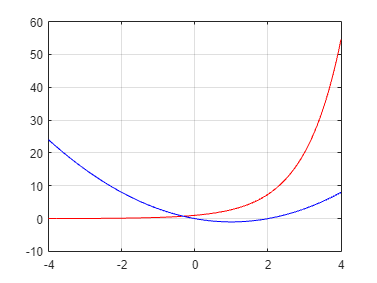

yy2=f2(xx);
plot(xx,yy1,'r',xx,yy2,'b')
grid on

### Ejercicio 2

syms x
f=matlabFunction(-x^2+2*x+exp(x));
a=-1;b=0;
if f(a)*f(b)<0
fprintf('Existe al menos una raiz')
else
fprintf('No se puede afirmar que existe una raiz')
end

Existe al menos una raiz

### Metodo biseccion Ejemplo 1

f=matlabFunction(-x^2+2*x+exp(x));
a=-1;b=0;maxiter=10;
z=biseccion_Maxiter(f,a,b,maxiter)

z =                    0  -1.000000000000000                   0  -0.500000000000000  -2.632120558828558   1.000000000000000  -0.643469340287367   0.500000000000000
   1.000000000000000  -0.500000000000000                   0  -0.250000000000000  -0.643469340287367   1.000000000000000   0.216300783071405   0.250000000000000
   2.000000000000000  -0.500000000000000  -0.250000000000000  -0.375000000000000  -0.643469340287367   0.216300783071405  -0.203335721209028   0.125000000000000
   3.000000000000000  -0.375000000000000  -0.250000000000000  -0.312500000000000  -0.203335721209028   0.216300783071405   0.008959378946642   0.062500000000000
   4.000000000000000  -0.375000000000000  -0.312500000000000  -0.343750000000000  -0.203335721209028   0.008959378946642  -0.096557880062602   0.031250000000000
   5.000000000000000  -0.343750000000000  -0.312500000000000  -0.328125000000000  -0.096557880062602   0.008959378946642  -0.043643035669560   0.015625000000000
   6.000000000000000  -0.32812

z(length(z),4)

ans =   -0.314941406250000



fzero(f,a)

ans =   -0.315167824944275


fzero(f,b)

ans =   -0.315167824944275


### Ejemplo 2

f=matlabFunction(-x^2+2*x+exp(x));
a=-1;b=0;tol=10^(-3);
z=biseccion_Tol(f,a,b,tol)

Se necesita 9 iteraciones


z =                    0  -1.000000000000000                   0  -0.500000000000000  -2.632120558828558   1.000000000000000  -0.643469340287367   0.500000000000000
   1.000000000000000  -0.500000000000000                   0  -0.250000000000000  -0.643469340287367   1.000000000000000   0.216300783071405   0.250000000000000
   2.000000000000000  -0.500000000000000  -0.250000000000000  -0.375000000000000  -0.643469340287367   0.216300783071405  -0.203335721209028   0.125000000000000
   3.000000000000000  -0.375000000000000  -0.250000000000000  -0.312500000000000  -0.203335721209028   0.216300783071405   0.008959378946642   0.062500000000000
   4.000000000000000  -0.375000000000000  -0.312500000000000  -0.343750000000000  -0.203335721209028   0.008959378946642  -0.096557880062602   0.031250000000000
   5.000000000000000  -0.343750000000000  -0.312500000000000  -0.328125000000000  -0.096557880062602   0.008959378946642  -0.043643035669560   0.015625000000000
   6.000000000000000  -0.32812

z(length(z),4)

ans =   -0.315429687500000



fzero(f,a)

ans =   -0.315167824944275


fzero(f,b)

ans =   -0.315167824944275


### Ejercicio 3

Q=20;g=9.81;
f=@(z)(1 - (Q^2)*(3+z) / (g *(3*z + z^(2)/2)^3 ))

f = function_handle with value:
    @(z)(1-(Q^2)*(3+z)/(g*(3*z+z^(2)/2)^3))


a=1;b=2;tol=1e-4;
z=biseccion_Tol(f,a,b,tol)

Se necesita 13 iteraciones


z =                    0   1.000000000000000   2.000000000000000   1.500000000000000  -2.804055479771637   0.601809378185525  -0.030945998666012   0.500000000000000
   1.000000000000000   1.500000000000000   2.000000000000000   1.750000000000000  -0.030945998666012   0.601809378185525   0.378908870007410   0.250000000000000
   2.000000000000000   1.500000000000000   1.750000000000000   1.625000000000000  -0.030945998666012   0.378908870007410   0.206927176499928   0.125000000000000
   3.000000000000000   1.500000000000000   1.625000000000000   1.562500000000000  -0.030945998666012   0.206927176499928   0.097956238334015   0.062500000000000
   4.000000000000000   1.500000000000000   1.562500000000000   1.531250000000000  -0.030945998666012   0.097956238334015   0.036260860504531   0.031250000000000
   5.000000000000000   1.500000000000000   1.531250000000000   1.515625000000000  -0.030945998666012   0.036260860504531   0.003383090117061   0.015625000000000
   6.000000000000000   1.50000


z(length(z),4)

ans =    1.514099121093750



fzero(f,a)

ans =    1.514054736734626


fzero(f,b)

ans =    1.514054736734626


### Newton Ejercicio 1

f=matlabFunction(x^2-2*x-3);
x0=-4; tol=1e-3;
z=newton_Tol(f,x0,tol)

z =                    0  -4.000000000000000
   1.000000000000000  -1.900000000000000
   2.000000000000000  -1.139655172413793
   3.000000000000000  -1.004557642613021
   4.000000000000000  -1.000005181219474
   5.000000000000000  -1.000000000006711


fzero(f,x0)

ans =     -1


### Ejercicio 2

R=3;V=30;h0=2; tol=1e-3;maxiter=3;
f= @(h)( V - (pi* h^2)* (3*R- h)/3 );
z=newton_Tol_Maxiter(f,h0,tol,maxiter)

z =                    0   2.000000000000000   1.000000000000000
   1.000000000000000   2.026995406522548   0.013317941637007
   2.000000000000000   2.026905729281709   0.000044243419683


z(length(z),2)

ans =    2.026905729281709


fzero(f,h0)

ans =    2.026905728310013


### Ejercicio 3

syms x
g=matlabFunction(sqrt(2*x+3));
%Condicion de existencia
xx=[0:0.01:4];
yy=g(xx)

yy =    1.732050807568877   1.737814719698277   1.743559577416269   1.749285568453590   1.754992877478424   1.760681686165901   1.766352173265569   1.772004514666935   1.777638883463118   1.783255450012701   1.788854381999832   1.794435844492636   1.800000000000000   1.805547008526779   1.811077027627483   1.816590212458495   1.822086715828860   1.827566688249707   1.833030277982336   1.838477631085023   1.843908891458578   1.849324200890693   1.854723699099141   1.860107523773827   1.865475810617763   1.870828693386971   1.876166303929372   1.881488772222678   1.886796226411321   1.892088792842450   1.897366596101028   1.902629759044045   1.907878402833891   1.913112646970899   1.918332609325088   1.923538406167135   1.928730152198591   1.933907960581372   1.939071942966532   1.944222209522358   1.949358868961793   1.954482028569206   1.959591794226542   1.964688270438850   1.969771560359221   1.974841765813150   1.979898987322333   1.984943324127921   1.989974874213240   1.9949937343

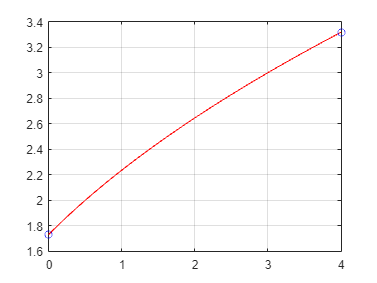

plot(xx,yy,'r',[0 4],[g(0) g(4)],'ob')
grid on

% Se visualiza que g([0;4]) in [0;4] ; % Condicion de unicidad
syms x
dg=diff(g(x))

$$dg = \frac{1}{\sqrt{2\,x+3}}$$

fudg=matlabFunction(dg)

fudg = function_handle with value:
    @(x)1.0./sqrt(x.*2.0+3.0)


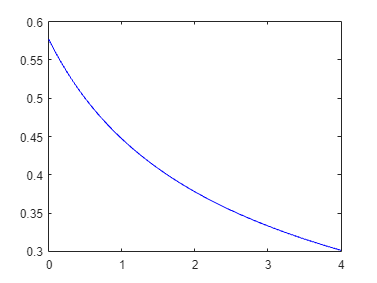

xx=[0:0.01:4];
yy1=abs(fudg(xx));
plot(xx,yy1,'b')

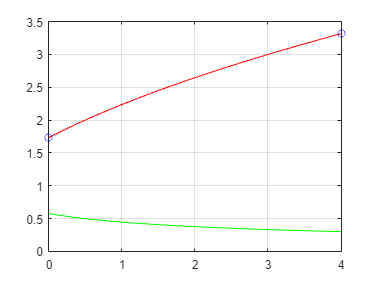

plot(xx,yy,'r',[0 4],[g(0) g(4)],'ob',xx,yy1,'green')
grid on

% Se visualiza que |g'(x)|<1 para x in [0;4]
x0=4;
Maxiter=10;
z=pfijo(g,x0,Maxiter)

z =    4.000000000000000
   3.316624790355400
   3.103747667048789
   3.034385495301739
   3.011440019426500
   3.003810919291193
   3.001270037597814
   3.000423315999865
   3.000141102014992
   3.000047033636303


### Ejercicio 4

u=200;M0=1600;g=9.8;c=27;t0=7.4375;vfinal=100;
v= @(t) (u * log(M0/(M0-c*t)) +g*t);
z=pfijo_result(v,t0,1000)

z =                    0   7.437500000000000
   1.000000000000000  99.709883647954484


## Semana 2 jueves

### Ejericicio 1

syms x y
f=[2*x-y-exp(-x);-x+2*y-exp(-y)]
%convertimos f a funci n
f=matlabFunction(f)
%calculamos el Jacobiano (en simbolico)
dF=jacobian(f(x,y),[x,y])

resultado=subs(dF,{x,y},{0,0})
resultado=double(resultado) %aqui ya esta en double

### Ejercicio 2 Met. Newton

format long
syms x y
f=[2*x-y-exp(-x);
    -x+2*y-exp(-y)]
x0=[0.5;1];
F=matlabFunction(f);
df=jacobian(F(x,y),[x,y])%calculando jacobiano
tol=1e-3;
error=1;
z=[x0' error]

while error>Tol
    x1=x0- inv(evalua(df,x0))*evalua(F,x0);
    error=norm(x1-x0,inf)/norm(x1,inf);
    z=[z;x1' error];
    x0=x1;
end
z

### Ejercicio 2

syms x y z
f=[3*x - cos(y*z)- 1/2;
    x^2 - 81*( (y+0.1)^2 )+ sin(z) + 1.6;
    exp(-x*y)+20*z+(10*pi-3)/3];
x0=[0.1;0.1;-0.1];
F=matlabFunction(f);
df=jacobian(F(x,y,z),[x,y,z])
tol=1e-4;
error=1;
z=[x0' error];
while error>tol
    x1= x0-inv(evalua1(df,x0))*evalua1(F,x0);
    error= norm(x1-x0,inf)/norm(x1,inf);
    z=[z;x1' error];
    x0=x1;
end
z

### Puntos fijos Ejercicio 1

syms x y
G=[(y+exp(-x))/2;(x+exp(-y))/2]
G=matlabFunction(G)
dG=jacobian(G(x,y),[x,y])
M=double(subs(dG,{x,y},{0.5,1}))
norm(M,inf)

syms x y
u = (y+exp(-x))/2; %x
v = (x+exp(-y))/2; %y
G = [u; v]
G = matlabFunction(G);
x0 = [0.5; 1]
crit_conv(G,x0) %debe ser menor a 1 para poder usar el método del punto fijo
Tol=1e-4;
pfijos(G,x0,Tol)

### Ejercicio 2

syms x y z 
f=[3*x - cos(y*z)- 1/2;
    x^2 - 81*( (y+0.1)^2 )+ sin(z) + 1.6;
    exp(-x*y)+20*z+(10*pi-3)/3];
x0=[0.1;0.1;-0.1];
F=matlabFunction(f);

crit_conv3(F,x0)
pfijos3(F,x0,Tol)

## Semana 3 martes

### Ejercicio 1

A=[3 1 6; 8 10 4; 1 9 12]

A =      3     1     6
     8    10     4
     1     9    12


D=diag(diag(A))

D =      3     0     0
     0    10     0
     0     0    12


L=-tril(A,-1)

L =      0     0     0
    -8     0     0
    -1    -9     0


U=-tril(A,1)

U =     -3    -1     0
    -8   -10    -4
    -1    -9   -12


D-L-U

ans =      6     1     0
    16    20     4
     2    18    24


### Ejericio 2

A=[10 -1 2 0; 
  -1 11 -1 3;
   2 -1 10 -1;
   0 3 -1 8];
b=[6;25;-11;15];
x0=zeros(4,1)

x0 =      0
     0
     0
     0


tol=1e-3;
z=jacobi_tol(A,b,x0,tol)

z =                    0                   0                   0                   0   1.000000000000000
   0.600000000000000   2.272727272727273  -1.100000000000000   1.875000000000000   1.000000000000000
   1.047272727272727   1.715909090909091  -0.805227272727273   0.885227272727273   0.576821192052980
   0.932636363636364   2.053305785123967  -1.049340909090909   1.130880681818182   0.164318776413765
   1.015198760330579   1.953695764462810  -0.968108626033058   0.973842716942149   0.080379948471257
   0.988991301652893   2.011414725770098  -1.010285903925620   1.021350510072314   0.028695703858482
   1.003198653362134   1.992241260682758  -0.994521736746337   0.994433739845511   0.013510798495147
   0.998128473417543   2.002306881552661  -1.001972230619600   1.003594310150674   0.005027012074242
   1.000625134279186   1.998670301122357  -0.999035575513175   0.998888390590302   0.002354525184934
   0.999674145214871   2.000447671545010  -1.000369157684571   1.000619190139969   0.00

### Ejericico 3

A=[4 2 1;1 5 3;2 6 9];
b=[9;14;23];
x0=[0.5;1;0.5];
maxiter=10;
z=jacobi_Maxiter(A,b,x0,1e-3,maxiter)

z =                    0   0.500000000000000   1.000000000000000   0.500000000000000   1.000000000000000
   1.000000000000000   1.625000000000000   2.400000000000000   1.777777777777778   0.583333333333333
   2.000000000000000   0.605555555555555   1.408333333333333   0.594444444444444   0.840236686390533
   3.000000000000000   1.397222222222222   2.322222222222223   1.482098765432099   0.393540669856459
   4.000000000000000   0.718364197530864   1.631296296296296   0.696913580246913   0.481325916676127
   5.000000000000000   1.260123456790124   2.238179012345680   1.308388203017832   0.273201839262211
   6.000000000000000   0.803813443072702   1.762942386831276   0.783408779149519   0.297785921871171
   7.000000000000000   1.172676611796982   2.169192043895748   1.201635421429660   0.192802957883355
   8.000000000000000   0.864995122694711   1.844483424782808   0.848832723670172   0.191274528694142
   9.000000000000000   1.115550106691053   2.117701341258955   1.133678800657081   0.13

### Gauss Seidel Ejercicio 1

A=[10 -1 2 0; 
  -1 11 -1 3;
   2 -1 10 -1;
   0 3 -1 8];
b=[6;25;-11;15];
x0=zeros(4,1);
tol=1e-3;
z=gausseidel_tol(A,b,x0,tol)

z =                    0                   0                   0                   0   1.000000000000000
   0.600000000000000   2.327272727272728  -0.987272727272727   0.878863636363636   1.000000000000000
   1.030181818181818   2.036938016528926  -1.014456198347107   0.984341219008264   0.211190431270401
   1.006585041322314   2.003555016904583  -1.002527384673178   0.998350945576634   0.016661883173998
   1.000860978625094   2.000298250656547  -1.000307276101701   0.999849746491082   0.002861604610883
   1.000091280285995   2.000021342246459  -1.000031147183445   0.999988103259647   0.000384845062821


### Ejercicio 2

A=[4 2 1;1 5 3;2 6 9];
b=[9;14;23];
x0=[0.5;1;0.5];
maxiter=10;
tol=1e-4;
z=gausseidel_Maxiter(A,b,x0,tol,maxiter)

z =                    0   0.500000000000000   1.000000000000000   0.500000000000000   1.000000000000000
   1.000000000000000   1.625000000000000   2.175000000000000   0.744444444444444   0.540229885057471
   2.000000000000000   0.976388888888889   2.158055555555556   0.899876543209876   0.300553481786588
   3.000000000000000   0.946003086419753   2.070873456790124   0.964750342935528   0.042099191758711
   4.000000000000000   0.973375685871056   2.026474657064472   0.988266742874561   0.021909378225320
   5.000000000000000   0.989695985749123   2.009100757125438   0.996222609527680   0.008647600115333
   6.000000000000000   0.996393969055361   2.002987640472320   0.998809579895039   0.003343996323741
   7.000000000000000   0.998803784790080   2.000953495104961   0.999630162198897   0.001204333704214
   8.000000000000000   0.999615711897796   2.000298760301103   0.999886223821977   0.000405902920018
   9.000000000000000   0.999879063893955   2.000092452928023   0.999965239404883   0.00

### Convergencia Ejercicio 1

A=[-8 1 6;8 13 4;1 9 -10]

A =     -8     1     6
     8    13     4
     1     9   -10


op=diagdom(A)

m =      3


n =      3


No es diagonal estrictamente dominante

op =      1


### Radio espectral

A=[10 -1 2 0;-1 11 -1 3;2 -1 10 -1; 0 3 -1 8]

A =     10    -1     2     0
    -1    11    -1     3
     2    -1    10    -1
     0     3    -1     8


D=diag(diag(A));
L=-tril(A,-1);
U=-triu(A,1);

Tj=inv(D)*(L+U);
Tgs=inv(D-L)*U;
%calculando los radios
rho_j=max(abs(eig(Tj)))

rho_j =    0.426436610842342


rho_gs=max(abs(eig(Tgs)))

rho_gs =    0.089823058388043


## Funciones semana 1 Martes

### Funcion exponencial

function e= expo(x,n)
    e=0;
    for i=0:n
        e= e + (x^i)/factorial(i);
    end
end

### Calcular cifras significativas

function CS = cifras_sig(error)
    k = 0;
    while error <=5*10^(-k)
        k = k + 1;
    end
    CS = k-1;
end

### Funcion coseno

function [S,k] = coseno(x)
    S = 0;
    k = 0;
    CS = 0;
    A = cos(x);
    while CS < 8
        S = S + ((-1)^k) * (x^(2*k))/factorial(2*k);
        ER = abs((A-S)/S);
        CS = cifras_sig(ER);
        k = k + 1;
    end
end

### Funcion expo matrix

function [S,n]= expo_matrix(M)
    S=0;n=0;CS=0;
    A=expm(M);
    while CS<8
        S= S +(M^n)/factorial(n);
        Er= abs((A-S)/A);
        CS=cifras_sig(Er);
        n=n+1;
    end
end

## Funcion semana 1 jueves

### Funcion redond

function y=redond(x,n)
    %Devuelve x redondeado a n cifras significativas.
    if x==0
        y=0;
    else
        s=sign(x);
        expo=ceil(log(abs(x))/log(10));
        mant=exp(log(abs(x))-expo*log(10));
        nm=round(mant*10^n)/(10^n);
        y=s*nm*10^expo;
    end
end
function y=suma(a,b,n)
    y=redond(redond(a,n)+redond(b,n),n);
end
function y=resta(a,b,n)
    y=redond(redond(a,n)-redond(b,n),n);
end
function y=prod(a,b,n)
    y=redond(redond(a,n)*redond(b,n),n);
end
function y=div(a,b,n)
    y=redond(redond(a,n)/redond(b,n),n);
end
function y=raiz(a,n)
    y=redond(sqrt(redond(a,n)),n);
end

%para el ejercicio 6
function [x1,x2]=cuadratica(a,b,c,n)
    x1=div(suma(-b,raiz(resta(prod(b,b,n),4*prod(a,c,n),n),n),n),...
    prod(2,a,n),n);
    x2=div(resta(-b,raiz(resta(prod(b,b,n),4*prod(a,c,n),n),n),n),...
    prod(2,a,n),n);
end

## Funcion semana 2 Martes

### Metodo de biseccion con iteraciones

function z= biseccion_Maxiter(f,a,b,maxiter)
    c=(a+b)/2;
    error=(b-a)/2;
    iter= 0;
    z=[iter a b c f(a) f(b) f(c) error];

    for iter=1:maxiter
        if f(a)*f(c)<0
            b=c;
        else
            a=c;
        end
        c=(b+a)/2;
        error=(b-a)/2;
        z=[z; iter a b c f(a) f(b) f(c) error];
    end
end

### Metodo de biseccion con tolerancia

function z=biseccion_Tol(f,a,b,Tol)
    c=(a+b)/2;
    error=(b-a)/2;
    iter=0;
    z=[iter a b c f(a) f(b) f(c) error];
    N=ceil(log((b-a)/(2*Tol))/log(2));
    fprintf('Se necesita %d iteraciones\n',N)
    while error>Tol
        if f(a)*f(c)<0
         b=c;
        else
         a=c;
        end
         c=(a+b)/2;
         error=(b-a)/2;
         iter= iter+1;
         z=[z;iter a b c f(a) f(b) f(c) error];
    end
end

### Funcion Newton

function z=newton_Tol(f,x0,tol)
    syms x
    df=diff(f(x));
    dfu=matlabFunction(df);
    iter= 0;
    z=[iter x0];
    error=1;
    while error>tol
        x1= x0 - f(x0)/dfu(x0);
        iter=iter+1;
        z=[z;iter x1];
        error=abs(x1-x0)/abs(x1);
        x0=x1;
    end
end

### Funcion Newton-error

function z=newton_Tol_Maxiter(f,x0,tol,maxiter)
    syms x
    df=diff(f(x));
    dfu=matlabFunction(df);
    iter= 0;
    error=1;
    z=[iter x0 error];
    while error>tol && iter<maxiter
        x1= x0 - f(x0)/dfu(x0);
        iter=iter+1;
        error=abs(x1-x0)/abs(x1);
        z=[z;iter x1 error];
        x0=x1;
    end
end

### Funcion punto fijo

function z=pfijo(g,x0,Maxiter)
    z=[x0];
    for k=1:Maxiter
        x1=g(x0);
        z=[z;x1];
        x0=x1;
    end
end
function z=pfijo_result(g,x0,result)
    iter=0;
    z=[iter x0];
    while g(x0)<=result
        x1=g(x0);
        iter=iter+1;
        z=[z;iter x1];
        x0=x1;
    end
end

## Funcion semana 2 Jueves

### Funcion evalua para Newton de varias variables

function z = newton_variasvariables(F,x0,Tol)
    syms x y
    dF = jacobian(F(x,y),[x,y]);
    error = 1;
    z = [x0' error]; %x y e
    iter = 0;
    while error > Tol
        x1 = x0 - inv(evalua(dF,x0)) * evalua(F,x0); 
        error = norm(x1-x0,inf)/norm(x1,inf); %error relativo
        z = [z; x1' error];
        x0 = x1;
        iter = iter + 1;
    end
    iter
    CS = cifras_sig(error)
end

function m=evalua(F,x0) %evaluar funcion
    syms x y
    m=double(subs(F,{x,y},{x0(1),x0(2)}));
end
function m=evalua1(F,x0) %evaluar funcion
    syms x y z 
    m=double(subs(F,{x,y,z},{x0(1),x0(2),x0(3)}));
end

### Funcion puntos fijos

function z=pfijos_Tol(g,x0,Tol)
    error=1;
    z=[g(x0(1),x0(2))' error];
    while error>Tol
        x1=g(x0(1),x0(2));
        error=norm(x1-x0,inf)/norm(x1);
        z=[z;x1' error];
        x0=x1;
    end
end

### Criterio de convergencia

function s=crit_conv(G,x0)
    syms x y
    dG = jacobian(G(x,y),[x,y]);
    M = double(subs(dG,{x,y},{x0(1),x0(2)}));
    s = norm(M,inf);
    if s < 1 %debe ser menor que 1 para poder usar el método del punto fijo
        fprintf("Cumple el criterio de convergencia.")
    else
        fprintf("NO cumple el criterio de convergencia.")
    end
end

### Para 3 variables

function z=pfijos_3variables_tol(g,x0,Tol)
    error = 1;
    z = [g(x0(1),x0(2),x0(3))' error];
    while error > Tol
        x1 = g(x0(1),x0(2),x0(3));
        error = norm(x1-x0,inf)/norm(x1);
        z = [z;x1' error];
        x0=x1;
    end
end

### Criterio de convergencia para 3 variables

function s=crit_conv3variables(G,x0)
    syms x y z
    dG = jacobian(G(x,y,z),[x,y,z]);
    M = double(subs(dG,{x,y,z},{x0(1),x0(2),x0(3)}));
    s = norm(M,inf);
    if s < 1 %debe ser menor que 1 para poder usar el método del punto fijo
        fprintf("Cumple el criterio de convergencia.")
    else
        fprintf("NO cumple el criterio de convergencia.")
    end
end

## Funcion semana 3 Martes

### Funcion Jacobi

function [z]=jacobi_tol(A,b,x0,Tol)
    D=diag(diag(A));
    L=-tril(A,-1);
    U=-triu(A,1);

    Tj=inv(D)*(L+U);
    cj=inv(D)*b;
    error=1;
    z=[x0' error];
    while error>Tol
        x1=Tj*x0+cj;
        error=norm(x1-x0,inf)/norm(x1,inf);
        z=[z;x1' error];
        x0=x1;
    end
end
function [z]=jacobi_Maxiter(A,b,x0,Tol,maxiter)
    D=diag(diag(A));
    L=-tril(A,-1);
    U=-triu(A,1);
    k=0;
    Tj=inv(D)*(L+U);
    cj=inv(D)*b;
    error=1;
    z=[k x0' error];
    while error>Tol && k<maxiter
        x1=Tj*x0+cj;
        error=norm(x1-x0,inf)/norm(x1,inf);
        k=k+1;
        z=[z;k x1' error];
        x0=x1;
    end
end

### Jacobi version 2

function [x k]=jacobi_2version(A,b,x0)
    %recibe como entradas la matriz A, vector b y pto semilla x0
    %devuelve la solucion y la cantidad de iteraciones
    n=length(b);
    x=x0;
    k=0; %numero de iteraciones
    error=1;
    tol=0.001
    d=diag(A);
    r=A-diag(d);
    while error>tol
        y=(b-r*x)./d;
        error=max(abs(x-y))/max(abs(y));
        x=y;
        k=k+1;
    end
end

### Gauss Seidel

function [z]=gausseidel_tol(A,b,x0,Tol)
    D=diag(diag(A));
    L=-tril(A,-1);
    U=-triu(A,1);
    Tgs=inv(D-L)*U;
    cgs=inv(D-L)*b;
    error=1;
    z=[x0' error];
    while error>Tol
        x1=Tgs*x0+cgs;
        error=norm(x1-x0,inf)/norm(x1,inf);
        z=[z;x1' error];
        x0=x1;
    end
end
function [z]=gausseidel_Maxiter(A,b,x0,Tol,maxiter)
    D=diag(diag(A));
    L=-tril(A,-1);
    U=-triu(A,1);
    Tgs=inv(D-L)*U;
    cgs=inv(D-L)*b;
    error=1;
    k=0;
    z=[k x0' error];
    while error>Tol && k<maxiter
        x1=Tgs*x0+cgs;
        error=norm(x1-x0,inf)/norm(x1,inf);
        k=k+1;
        z=[z;k x1' error];
        x0=x1;
    end
end

### Convergencia 

function op=diagdom(A)
    %op=0: diagonal estrictamente dominante
    %op=1: No es diagonal estrictamente dominante
    [m,n]=size(A)
    op=0;
    if m==n
        for k=1:m
            if abs(A(k,k))<=sum(abs(A(k,:)))-abs(A(k,k))
                op=1;
                break;
            end
        end
    end
    
    if op
        fprintf('No es diagonal estrictamente dominante');
    else
        fprintf('diagonal estrictamente dominante');
    end
end